# 准备区

clear;
clc;

## 参数加载

load('data\excit_filtering.mat');
Symbol_Definition;
g = 9.80665;

[n_sample, ~] = size(q_filt);
n_parameters = 43;
ww = zeros(n_sample * 7, n_parameters);

## 符号矩阵和函数的计算过程

% 计算回归矩阵
Dynamic_Identification_Model;
regression_matrix_symbol = [
%ZZR1 XXR2   XY2     XZ2     YZ2     ZZR2   MX2  MYR2  XXR3   XY3     XZ3     YZ3     ZZR3   MX3    MYR3   XXR4   XY4     XZ4     YZ4     ZZR4   MX4    MYR4    XXR5   XY5     XZ5     YZ5     ZZR5   MX5    MYR5   XXR6   XY6     XZ6     YZ6     ZZR6   MX6    MYR6    XXR7   XY7     XZ7     YZ7     ZZR7   MX7    MYR7   FS1       FV1 FS2       FV2 FS3       FV3 FS4       FV4 FS5       FV5 FS6       FV6 FS7       FV7 
QDP1 N13XX2 N13XY2  N13XZ2  N13YZ2  N13ZZ2 0    0     N13XX3 N13XY3  N13XZ3  N13YZ3  N13ZZ3 N13MX3 N13MY3 N13XX4 N13XY4  N13XZ4  N13YZ4  N13ZZ4 N13MX4 N13MY4  N13XX5 N13XY5  N13XZ5  N13YZ5  N13ZZ5 N13MX5 N13MY5 N13XX6 N13XY6  N13XZ6  N13YZ6  N13ZZ6 N13MX6 N13MY6  N13XX7 N13XY7  N13XZ7  N13YZ7  N13ZZ7 N13MX7 N13MY7;
0    -DV22  No23XY2 No23XZ2 No23YZ2 QDP2   VP22 -VP12 N23XX3 N23XY3  N23XZ3  N23YZ3  N23ZZ3 N23MX3 N23MY3 N23XX4 N23XY4  N23XZ4  N23YZ4  N23ZZ4 N23MX4 N23MY4  N23XX5 N23XY5  N23XZ5  N23YZ5  N23ZZ5 N23MX5 N23MY5 N23XX6 N23XY6  N23XZ6  N23YZ6  N23ZZ6 N23MX6 N23MY6  N23XX7 N23XY7  N23XZ7  N23YZ7  N23ZZ7 N23MX7 N23MY7;
0    0      0       0       0       0      0    0     -DV23  No33XY3 No33XZ3 No33YZ3 WP33   VP23   -VP13  N33XX4 N33XY4  N33XZ4  N33YZ4  N33ZZ4 N33MX4 -N31MX4 N33XX5 N33XY5  N33XZ5  N33YZ5  N33ZZ5 N33MX5 N33MY5 N33XX6 N33XY6  N33XZ6  N33YZ6  N33ZZ6 N33MX6 N33MY6  N33XX7 N33XY7  N33XZ7  N33YZ7  N33ZZ7 N33MX7 N33MY7;
0    0      0       0       0       0      0    0     0      0       0       0       0      0      0      -DV24  No43XY4 No43XZ4 No43YZ4 WP34   VP24   -VP14   N43XX5 N43XY5  N43XZ5  N43YZ5  N43ZZ5 N43MX5 N43MY5 N43XX6 N43XY6  N43XZ6  N43YZ6  N43ZZ6 N43MX6 N43MY6  N43XX7 N43XY7  N43XZ7  N43YZ7  N43ZZ7 N43MX7 N43MY7;
0    0      0       0       0       0      0    0     0      0       0       0       0      0      0      0      0       0       0       0      0      0       -DV25  No53XY5 No53XZ5 No53YZ5 WP35   VP25   -VP15  N53XX6 N53XY6  N53XZ6  N53YZ6  N53ZZ6 N53MX6 -N51MX6 N53XX7 N53XY7  N53XZ7  N53YZ7  N53ZZ7 N53MX7 N53MY7;
0    0      0       0       0       0      0    0     0      0       0       0       0      0      0      0      0       0       0       0      0      0       0      0       0       0       0      0      0      -DV26  No63XY6 No63XZ6 No63YZ6 WP36   VP26   -VP16   N63XX7 N63XY7  N63XZ7  N63YZ7  N63ZZ7 N63MX7 N63MY7; 
0    0      0       0       0       0      0    0     0      0       0       0       0      0      0      0      0       0       0       0      0      0       0      0       0       0       0      0      0      0      0       0       0       0      0      0       -DV27  No73XY7 No73XZ7 No73YZ7 WP37   VP27   -VP17 ; 
];

ww_function = ww;
ww_symbol = ww;
for k = 1 : n_sample
    q = q_filt(k, :);
    qd = qd_filt(k, :);
    qdd = qdd_filt(k, :);
    
    th1 = q(1); QP1 = qd(1); QDP1 = qdd(1);
    th2 = q(2); QP2 = qd(2); QDP2 = qdd(2);
    th3 = q(3); QP3 = qd(3); QDP3 = qdd(3);
    th4 = q(4); QP4 = qd(4); QDP4 = qdd(4);
    th5 = q(5); QP5 = qd(5); QDP5 = qdd(5);
    th6 = q(6); QP6 = qd(6); QDP6 = qdd(6);
    th7 = q(7); QP7 = qd(7); QDP7 = qdd(7);

    start_row = 1 + (k - 1) * 7;
    end_row = k * 7;

    ww_symbol(start_row : end_row, :) = eval(subs(regression_matrix_symbol, ...
        {'g', 'th1', 'QP1', 'QDP1', ...
              'th2', 'QP2', 'QDP2', ...
              'th3', 'QP3', 'QDP3', ...
              'th4', 'QP4', 'QDP4', ...
              'th5', 'QP5', 'QDP5', ...
              'th6', 'QP6', 'QDP6', ...
              'th7', 'QP7', 'QDP7'}, ...
        { g ,  th1 ,  QP1 ,  QDP1 , ...
               th2 ,  QP2 ,  QDP2 , ...
               th3 ,  QP3 ,  QDP3 , ...
               th4 ,  QP4 ,  QDP4 , ...
               th5 ,  QP5 ,  QDP5 , ...
               th6 ,  QP6 ,  QDP6 , ...
               th7 ,  QP7 ,  QDP7 }));
    ww_function(start_row : end_row, :) = compute_regression_matrix(q, qd, qdd, 0);

    fprintf('完成第%d帧数据的计算\n', k);
end

完成第1帧数据的计算
完成第2帧数据的计算
完成第3帧数据的计算
完成第4帧数据的计算
完成第5帧数据的计算
完成第6帧数据的计算
完成第7帧数据的计算
完成第8帧数据的计算
完成第9帧数据的计算
完成第10帧数据的计算
完成第11帧数据的计算
完成第12帧数据的计算
完成第13帧数据的计算
完成第14帧数据的计算
完成第15帧数据的计算
完成第16帧数据的计算
完成第17帧数据的计算
完成第18帧数据的计算
完成第19帧数据的计算
完成第20帧数据的计算
完成第21帧数据的计算
完成第22帧数据的计算
完成第23帧数据的计算
完成第24帧数据的计算
完成第25帧数据的计算
完成第26帧数据的计算
完成第27帧数据的计算
完成第28帧数据的计算
完成第29帧数据的计算
完成第30帧数据的计算
完成第31帧数据的计算
完成第32帧数据的计算
完成第33帧数据的计算
完成第34帧数据的计算
完成第35帧数据的计算
完成第36帧数据的计算
完成第37帧数据的计算
完成第38帧数据的计算
完成第39帧数据的计算
完成第40帧数据的计算
完成第41帧数据的计算
完成第42帧数据的计算
完成第43帧数据的计算
完成第44帧数据的计算
完成第45帧数据的计算
完成第46帧数据的计算
完成第47帧数据的计算
完成第48帧数据的计算
完成第49帧数据的计算
完成第50帧数据的计算
完成第51帧数据的计算
完成第52帧数据的计算
完成第53帧数据的计算
完成第54帧数据的计算
完成第55帧数据的计算
完成第56帧数据的计算
完成第57帧数据的计算
完成第58帧数据的计算
完成第59帧数据的计算
完成第60帧数据的计算
完成第61帧数据的计算
完成第62帧数据的计算
完成第63帧数据的计算
完成第64帧数据的计算
完成第65帧数据的计算
完成第66帧数据的计算
完成第67帧数据的计算
完成第68帧数据的计算
完成第69帧数据的计算
完成第70帧数据的计算
完成第71帧数据的计算
完成第72帧数据的计算
完成第73帧数据的计算
完成第74帧数据的计算
完成第75帧数据的计算
完成第76帧数据的计算
完成第77帧数据的计算
完成第78帧数据的计算
完成第79帧数据的计算
完成第80帧数据的计算
完成第81帧数据的计算
完成第82帧数据的计算
完成第83帧数据的计算
完成第84帧数据的计算
完

## 对比

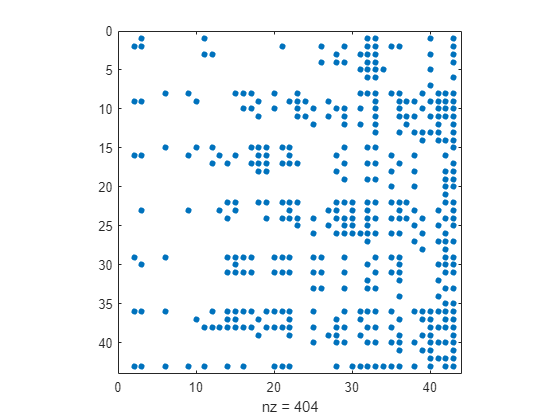

error = ww_symbol - ww_function;
spy(error(1: 43, 1:43));

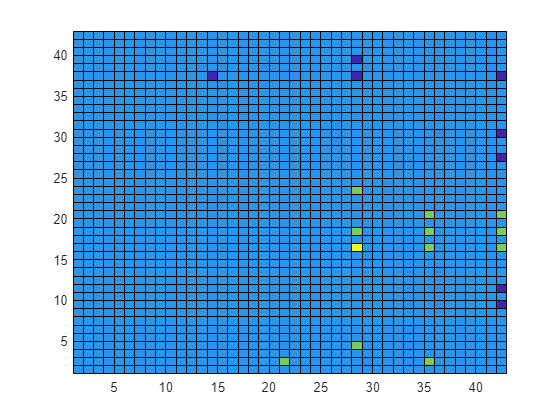

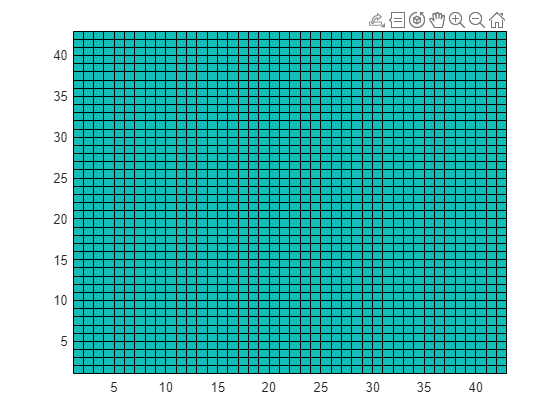

pcolor(error(1: 43, 1:43));

error

位置 2 处的索引超出数组边界。索引不能超过 1。

'error' 似乎同时为函数和变量。如果这不是预期的情况，请使用 'clear error' 将变量 'error' 从工作区中删除。